clear
close all

Ocean data import

Ocean_data = readtable('HAWI.csv', 'VariableNamingRule', 'preserve');
save('HAWI.mat', 'Ocean_data');
load('HAWI.mat');

Atmospheric data (CO₂) import

CO2_data = readtable('monthly_flask_co2_mlo.csv', 'VariableNamingRule', 'preserve');
save('monthly_flask_co2.mat', 'CO2_data');
load('monthly_flask_co2.mat');

Atmospheric data (C13) import

C13_data = readtable('monthly_flask_c13_mlo.csv', 'VariableNamingRule', 'preserve');
save('monthly_flask_c13.mat', 'C13_data');
load('monthly_flask_c13.mat');

Atmospheric data (O18) import

O18_data = readtable('monthly_flask_o18_mlo.csv', 'VariableNamingRule', 'preserve');
save('monthly_flask_o18.mat', 'O18_data');
load('monthly_flask_o18.mat');

**Anthoropogenic CO₂ and Isotopic Trends (Atmospheric Data)**

Plot time-series trend of anthropogenic CO₂ concentration at Mauna Loa Mauna Loa Observatory, Hawaii.

"The keeling curve" shows the long-term trend of rising CO₂ level.

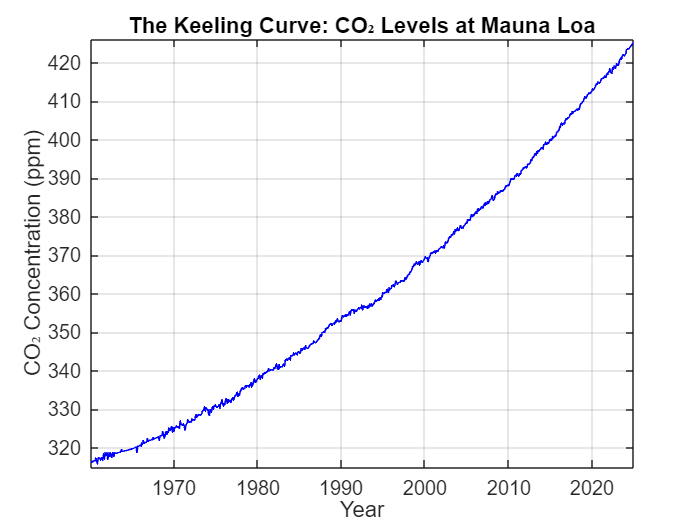

if exist('CO2_data', 'var')
    decimal_dates_CO2 = CO2_data.decimal_dateCO2; 
    season_adj_filled_CO2 = CO2_data{:, end}; 

    % Plot the Keeling Curve
    figure(1);
    clf
    plot(decimal_dates_CO2, season_adj_filled_CO2, 'b-', 'LineWidth', 1);
    title('The Keeling Curve: CO₂ Levels at Mauna Loa');
    xlabel('Year');
    ylabel('CO₂ Concentration (ppm)');
    grid on;
    xlim([min(decimal_dates_CO2), max(decimal_dates_CO2)]);
    ylim([floor(min(season_adj_filled_CO2)), ceil(max(season_adj_filled_CO2))]);
    set(gca, 'FontSize', 12);
end

The keeling curve was named after Charles David Keeling, it is a widely known iconic graph that depicts the long-term trend for atmospheric CO₂ concentrations at Mauna Loa, Hawaii. The curve shows an upward trend in CO₂ concentrations, starting from around 315 ppm to over 420 ppm from 1960 to the present. This reflects the increase of human activities, such as burning of fossil fuels, deforestation, and other industrial processes, which release large amounts of CO₂ into the atmosphere.

Plot time-series trend of atmospheric δ13C-CO₂ concentrations from 1980 to the present.

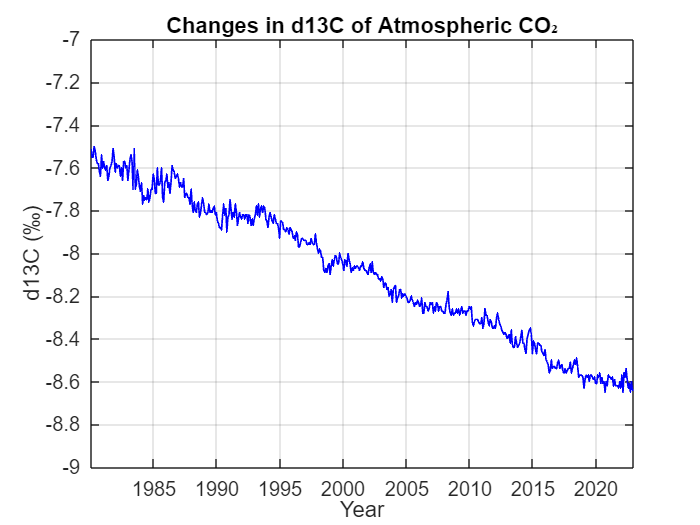

if exist('C13_data', 'var')
    decimal_dates_C13 = C13_data.decimal_dateC13; 
    season_adj_filled_C13 = C13_data{:, end}; 

    figure(2);
    clf
    plot(decimal_dates_C13, season_adj_filled_C13, 'b-', 'LineWidth', 1);
    title('Changes in d13C of Atmospheric CO₂');
    xlabel('Year');
    ylabel('d13C (‰)');
    grid on;
    xlim([min(decimal_dates_C13), max(decimal_dates_C13)]);
    ylim([floor(min(season_adj_filled_C13)), ceil(max(season_adj_filled_C13))]);
    set(gca, 'FontSize', 12);
end

The data shows a clear downward trend in d13C-CO₂ levels over the past 40 years. This decline reflects the addition of 12C from fossil fuel combustion. Fossil fuels, derived from ancient organic matter, contain lower concentrations of 13C compared to the atmosphere. When burned, they release carbon dioxide with a higher proportion of 12C, reducing the overall atmospheric 13C concentration.

Plot time-series trend of atmospheric δ18O-CO₂ concentrations from 1980 to the present.

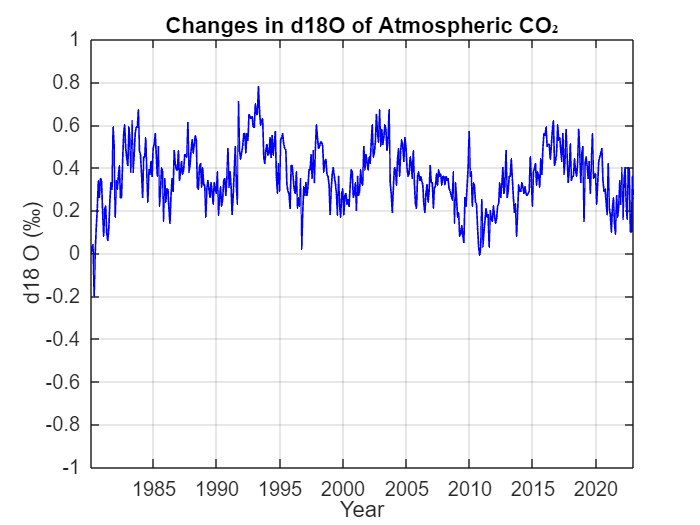

if exist('O18_data', 'var')
    decimal_dates_O18 = O18_data.decimal_dateO18; 
    season_adj_filled_O18 = O18_data{:, end}; 

    figure(3);
    clf
    plot(decimal_dates_O18, season_adj_filled_O18, 'b-', 'LineWidth', 1);
    title('Changes in d18O of Atmospheric CO₂');
    xlabel('Year');
    ylabel('d18 O (‰)');
    grid on;
    xlim([min(decimal_dates_O18), max(decimal_dates_O18)]);
    ylim([floor(min(season_adj_filled_O18)), ceil(max(season_adj_filled_O18))]);
    set(gca, 'FontSize', 12);
end

d18O-CO₂ levels remain relatively stable over this period, showing minimal fluctuation.

Plot the time-series of total DIC at the station "HAWI" from 1988 to 2016.

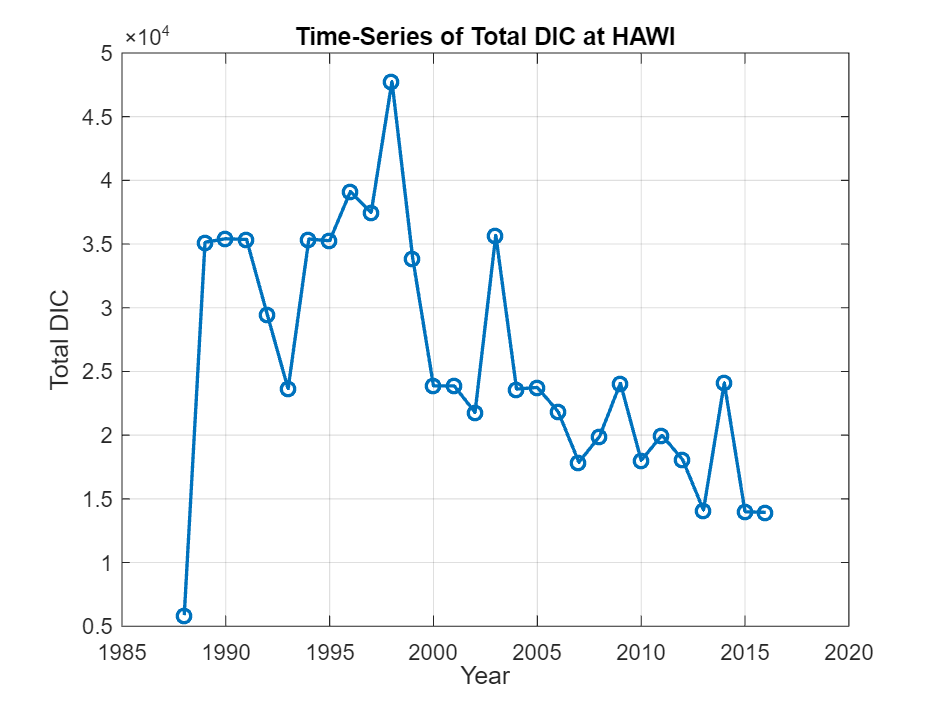

dates = Ocean_data.Date;
DIC = Ocean_data.DIC;

% Extract the year from the dates
years = year(dates);

% Group by year and calculate the total DIC for each year
unique_years = unique(years);
total_DIC_by_year = arrayfun(@(yr) sum(DIC(years == yr), 'omitnan'), unique_years);

figure(4);
plot(unique_years, total_DIC_by_year, '-o', 'LineWidth', 1.5);
xlabel('Year');
ylabel('Total DIC');
title('Time-Series of Total DIC at HAWI');
grid on;

In Figure 4, total DIC shows significant variability over the years, with an overall increase during the late 1980s and early 1990s, reaching a peak in 1998. After this peak, a gradual decline is observed, along with some fluctuations, until 2016. 

Plot the time-series of total d13C-DIC at the station "HAWI" from 1988 to 2016.

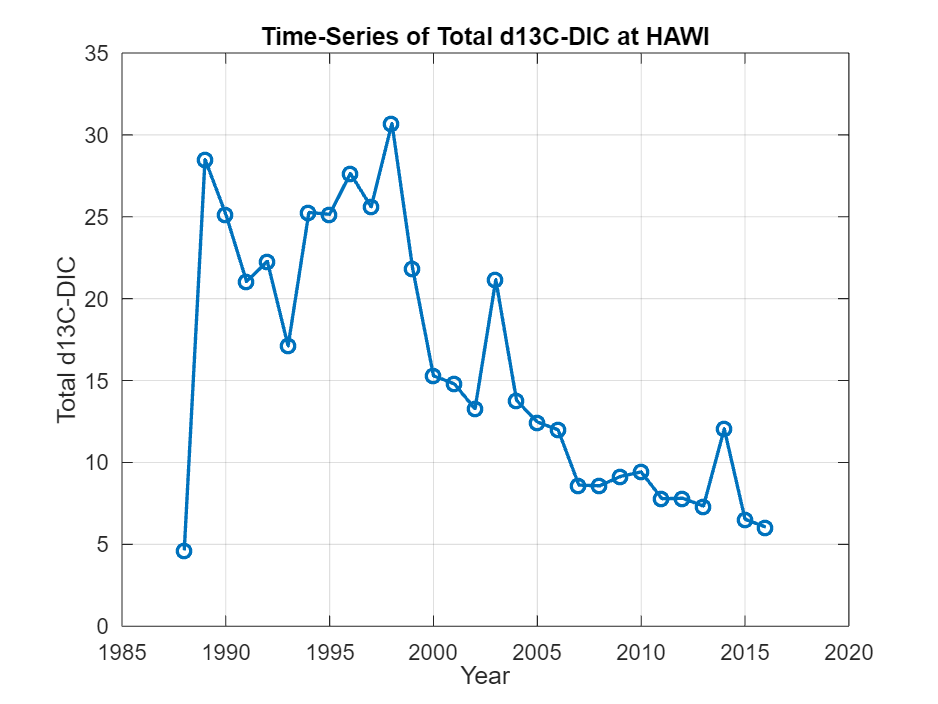

dates = Ocean_data.Date;      
d13C_DIC = Ocean_data.d13C_DIC;

% Extract the year
years = year(dates);

% Group by year and calculate the total d13C-DIC for each year
unique_years = unique(years);
total_d13C_DIC_by_year = arrayfun(@(yr) sum(d13C_DIC(years == yr), 'omitnan'), unique_years);

figure(5);
clf
plot(unique_years, total_d13C_DIC_by_year, '-o', 'LineWidth', 1.5);
xlabel('Year');
ylabel('Total d13C-DIC');
title('Time-Series of  Total d13C-DIC at HAWI');
grid on;

In Figure 5, the total d13C-DIC follows a similar pattern of variability but exhibits a sharper decline after its peak in 1998.  When CO₂ from fossil fuels is absorbed by the ocean, it lowers the d13C-DIC concentration in seawater. The decreasing trend in d13C-DIC highlights the increasing contribution of isotopically lighter carbon, likely from fossil fuel-derived CO₂, into the ocean.

**Investigate correlations between atmospheric CO₂ & seawater carbon chemistry. **

The graphs plot data points by aligning CO₂ and DIC measurements from the same year and month in the Hawaii region to ensure the accuracy of their relationship.

CO₂ vs DIC

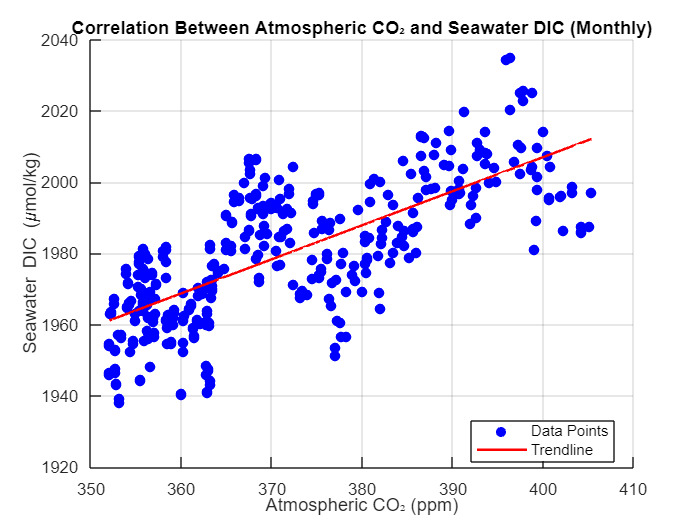

Correlation coefficient (R): 0.73


if exist('CO2_data', 'var') && exist('Ocean_data', 'var')
    % Extract year and month for CO2
    CO2_year = CO2_data.Yr_CO2;
    CO2_month = CO2_data.Mn_CO2; 
    season_adj_filled_CO2 = CO2_data{:, end};

    % Remove NaN values from CO2 data
    valid_CO2_indices = ~isnan(season_adj_filled_CO2);
    CO2_year = CO2_year(valid_CO2_indices);
    CO2_month = CO2_month(valid_CO2_indices);
    season_adj_filled_CO2 = season_adj_filled_CO2(valid_CO2_indices);

    % Convert ocean date to datetime format and extract year and month
    ocean_dates = datetime(Ocean_data.Date, 'InputFormat', 'yyyy-MM-dd');
    ocean_year = year(ocean_dates); 
    ocean_month = month(ocean_dates); 
    seawater_DIC = Ocean_data.DIC; 

    % Remove NaN values from Ocean data
    valid_DIC_indices = ~isnan(seawater_DIC);
    ocean_year = ocean_year(valid_DIC_indices);
    ocean_month = ocean_month(valid_DIC_indices);
    seawater_DIC = seawater_DIC(valid_DIC_indices);

    % Match both Data by Year and Month
    matched_CO2 = [];
    matched_DIC = [];
    for i = 1:length(ocean_year)
        match_idx = find(CO2_year == ocean_year(i) & CO2_month == ocean_month(i), 1);
        if ~isempty(match_idx)
            matched_CO2 = [matched_CO2; season_adj_filled_CO2(match_idx)];
            matched_DIC = [matched_DIC; seawater_DIC(i)];
        end
    end

    % Remove NaN values from matched data
    valid_indices = ~isnan(matched_CO2) & ~isnan(matched_DIC);
    matched_CO2 = matched_CO2(valid_indices);
    matched_DIC = matched_DIC(valid_indices);

    figure(6);
    scatter(matched_CO2, matched_DIC, 40, 'filled', 'MarkerFaceColor', 'b', 'DisplayName', 'Data Points');
    hold on;
    coefficients = polyfit(matched_CO2, matched_DIC, 1); % Linear regression
    trendline = polyval(coefficients, matched_CO2);
    plot(matched_CO2, trendline, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Trendline');
    hold off;
    title('Correlation Between Atmospheric CO₂ and Seawater DIC (Monthly)');
    xlabel('Atmospheric CO₂ (ppm)');
    ylabel('Seawater DIC (\mumol/kg)');
    legend('Location', 'best');
    grid on;

    % Correlation Coefficient
    correlation_coefficient = corr(matched_CO2, matched_DIC);
    fprintf('Correlation coefficient (R): %.2f\n', correlation_coefficient);
end

Figure 6 shows a correlation coefficient (R) of 0.73, indicating a strong positive correlation between atmospheric CO₂ and DIC in seawater. As atmospheric CO₂ concentrations increase, DIC levels in seawater also rise. This occurs because the ocean absorbs a significant portion of atmospheric CO₂, which then reacts with water to form carbonic acid. Carbonic acid dissociates into bicarbonate and carbonate ions, which are the primary components of DIC. 

CO₂ vs d13C-DIC

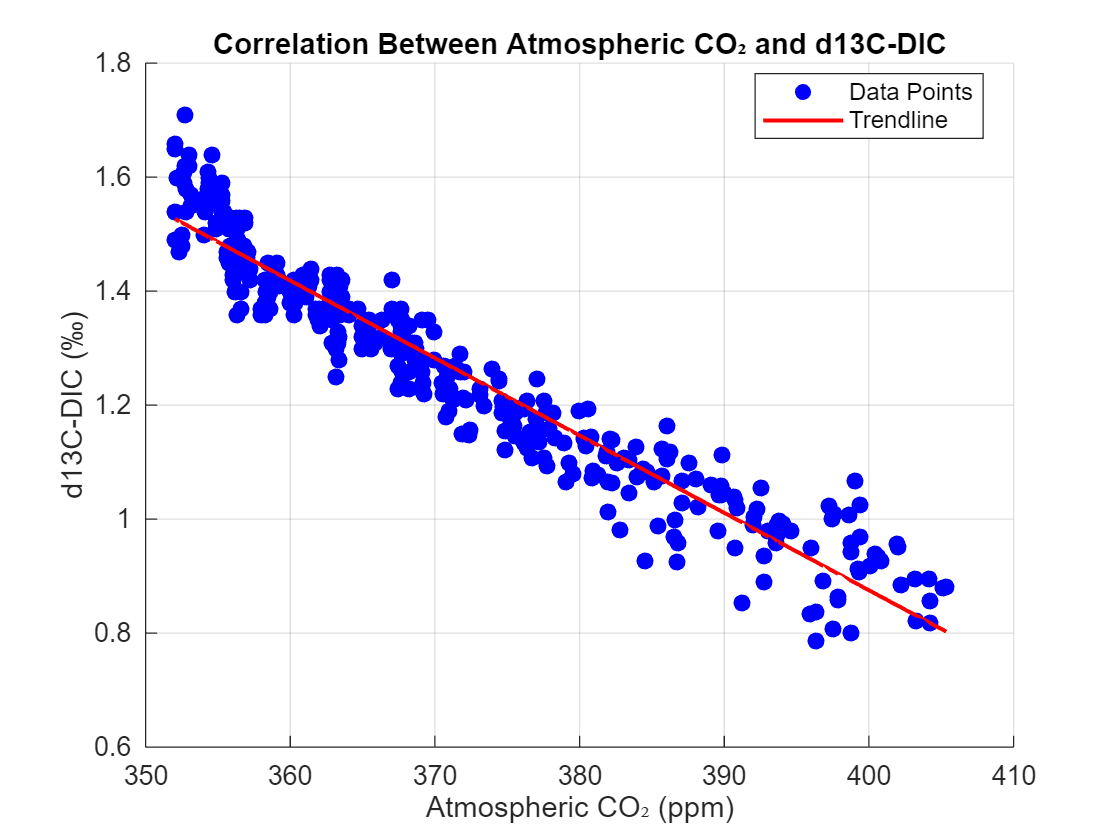

Correlation coefficient (R): -0.96


if exist('CO2_data', 'var') && exist('Ocean_data', 'var')
    % Extract year and month for CO2 data
    CO2_year = CO2_data.Yr_CO2; 
    CO2_month = CO2_data.Mn_CO2; 
    season_adj_filled_CO2 = CO2_data{:, end}; 

    % Remove NaN values from CO2 data
    valid_CO2_indices = ~isnan(season_adj_filled_CO2);
    CO2_year = CO2_year(valid_CO2_indices);
    CO2_month = CO2_month(valid_CO2_indices);
    season_adj_filled_CO2 = season_adj_filled_CO2(valid_CO2_indices);

    % Convert ocean date to datetime format and extract year and month
    ocean_dates = datetime(Ocean_data.Date, 'InputFormat', 'yyyy-MM-dd'); 
    ocean_year = year(ocean_dates);
    ocean_month = month(ocean_dates);
    d13C_DIC = Ocean_data.d13C_DIC;

    % Remove NaN values from Ocean data
    valid_D13C_indices = ~isnan(d13C_DIC);
    ocean_year = ocean_year(valid_D13C_indices);
    ocean_month = ocean_month(valid_D13C_indices);
    d13C_DIC = d13C_DIC(valid_D13C_indices);

    % Match Data by Year and Month
    matched_CO2 = [];
    matched_d13C = [];
    for i = 1:length(ocean_year)
        match_idx = find(CO2_year == ocean_year(i) & CO2_month == ocean_month(i), 1);
        if ~isempty(match_idx)
            matched_CO2 = [matched_CO2; season_adj_filled_CO2(match_idx)];
            matched_d13C = [matched_d13C; d13C_DIC(i)];
        end
    end

    % Remove NaN values from matched data
    valid_indices = ~isnan(matched_CO2) & ~isnan(matched_d13C);
    matched_CO2 = matched_CO2(valid_indices);
    matched_d13C = matched_d13C(valid_indices);

    figure(7);
    scatter(matched_CO2, matched_d13C, 40, 'filled', 'MarkerFaceColor', 'b', 'DisplayName', 'Data Points');
    hold on;
    coefficients = polyfit(matched_CO2, matched_d13C, 1); % Linear regression
    trendline = polyval(coefficients, matched_CO2);
    plot(matched_CO2, trendline, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Trendline');
    hold off;
    title('Correlation Between Atmospheric CO₂ and d13C-DIC');
    xlabel('Atmospheric CO₂ (ppm)');
    ylabel('d13C-DIC (‰)');
    legend('Location', 'best');
    grid on;

    % Display Correlation Coefficient
    correlation_coefficient = corr(matched_CO2, matched_d13C);
    fprintf('Correlation coefficient (R): %.2f\n', correlation_coefficient);
end

Figure 7 shows a correlation coefficient (R) of -0.96, demonstrating a very strong negative correlation between atmospheric CO₂ and d13C-DIC in seawater. As atmospheric CO₂ concentrations increase, d13C-DIC values in seawater decrease. This occurs because a significant portion of the additional CO₂ in the atmosphere comes from the combustion of fossil fuels that contain lighter carbon isotope (d13C). When this fossil-fuel-derived CO₂ is absorbed by the ocean, it mixes with the existing dissolved inorganic carbon (DIC), diluting the d13C levels. This process leads to a reduction in the overall d13C-DIC values in surface seawater.

**What are the seasonal variability/patterns of DIC? And how do they align with seasonal changes in seawater temperature?**

Plot DIC seasonal variability

ocean_dates = datetime(Ocean_data.Date, 'InputFormat', 'yyyy-MM-dd'); % Convert to datetime
ocean_year = year(ocean_dates); % Extract year
ocean_month = month(ocean_dates); % Extract month
seawater_DIC = Ocean_data.DIC; % Extract DIC values

% Calculate monthly averages for DIC
unique_months = 1:12;
monthly_avg_DIC = zeros(1, length(unique_months));
for m = unique_months
    monthly_avg_DIC(m) = mean(seawater_DIC(ocean_month == m), 'omitnan');
end

% Plot seasonal variability of DIC
figure(8);
plot(unique_months, monthly_avg_DIC, '-o', 'LineWidth', 1.5);
xticks(1:12);
xticklabels({'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', ...
              'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'});
xlabel('Month');
ylabel('DIC (µmol/kg)');
title('Seasonal Variability in Dissolved Inorganic Carbon (DIC)');
grid on;

Plot seawater temperature seasonal variability

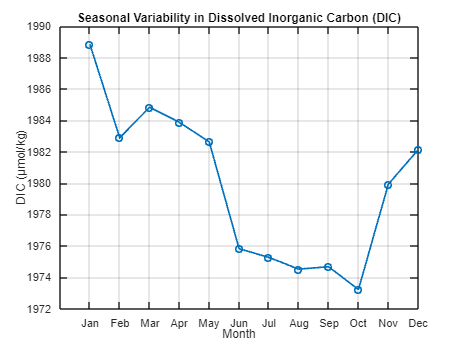

% Convert the date format and extract the month
ocean_dates = datetime(Ocean_data.Date, 'InputFormat', 'yyyy-MM-dd'); 
ocean_month = month(ocean_dates); 
seawater_temp = Ocean_data.Temp; 

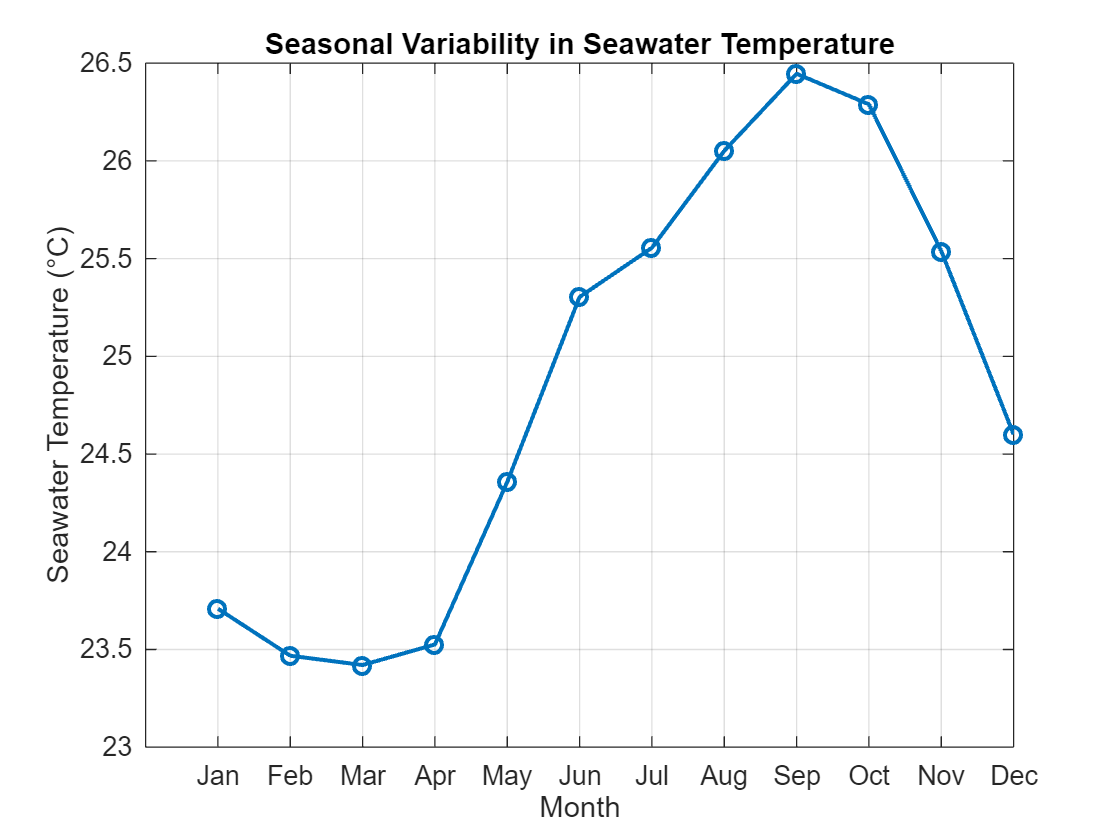


% Calculate monthly averages for temperature
unique_months = 1:12;
monthly_avg_temp = zeros(1, length(unique_months));
for m = unique_months
    monthly_avg_temp(m) = mean(seawater_temp(ocean_month == m), 'omitnan');
end

% Plot seasonal variability of seawater temperature
figure(9);
plot(unique_months, monthly_avg_temp, '-o', 'LineWidth', 1.5);
xticks(1:12);
xticklabels({'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', ...
              'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'});
xlabel('Month');
ylabel('Seawater Temperature (°C)');
title('Seasonal Variability in Seawater Temperature');
grid on;

There is an opposite relationship between DIC and seawater temperature, which implies that the concentration of DIC is the highest in winter (low seawater temperature) and lowest in summer/fall (highest seawater temperature.) This indicates that colder water can retain more dissolved CO₂, whereas rising temperatures reduce its solubility, resulting in lower DIC levels.